# Vectors and Matrices

In this notebook, we will:

- Learn how to create row vectors, column vectors, and matrices using MATLAB

- Make use of the `linspace` command to create evenly spaced arrays

- Learn how to extract information from arrays

- Perform operations on arrays. 

## **Arrays**

**Arrays** are used to store related data in one variable. Here is the terminology for different types of arrays: 

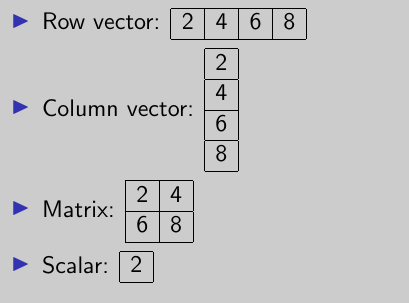

In the exercises that follow, you will practice creating such arrays. 

Create a row vector by entering the command `x = [3 4]`. Check your work by hitting `ctrl + enter.`

%% Code here.

x = [3 4]


You can use **semicolons** to create a new row in an array. Create the 3x1 column vector $\left[\begin{array}{ccc} 10 \\ -\pi^2 \\ \sqrt{10} \end{array}\right]$and store it in a variable called `y`.

%% Code here.

y = [10; -1*pi^2; sqrt(10)]


We can combine the syntax for row and column vectors to create matrices. Create the 2x2 matrix $\left[\begin{array}{cc} 1 & 2 \\ 0 & -5 \end{array}\right]$ and store it in a variable called `A.`

%% Code here. 

A = [1 2; 0 -5]


What happens if you enter the code `M = [3,4,5; 6,7,8]`?

%% Code here.

M = [3,4,5; 6,7,8]

## Evenly Spaced Row Vectors

What happens if you enter the code `M = [3:5; 6:8]?`

%% Code here.

M = [1:100; 101:200]

You can create a row vector of evenly spaced numbers using the `:` feature. If you want the space between numbers to be different from 1, use `[first_number:step_size:last_number]`

Create a row vector called `v `that starts at `1`, ends at `5`, and every element is separated by `0.5.`

 %% Code here.
 
v = [1:0.5:5]

We can also do this using the `linspace` command. Explore the documentation page for `linspace`. Then use it to create the following vectors:

- A vector `v1` consisting of 5 evenly spaced numbers between 0 and 1

- A vector v2 consisting of 5 evenly spaced numbers between 0 and 10.

- A vector v3 consisting of 4 evenly spaced numbers between 1 and 100. 

 %% Code here. 

 
v1 = linspace(0,1,5)
v2 = linspace(0,10,5)
 
 
 
 
 
 

As you might have observed above, to use `linspace, `simply enter the command `linspace(first_number, last_number, number_of_elements).`

## Column Vectors

How can we apply the commands we used above to create evenly spaced row vectors to create evenly spaced column vectors?

You might recall the **transpose** from linear algebra:

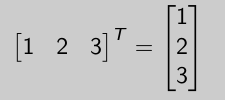

It turns out, we can transpose row vectors in MATLAB as well, using the `' `(apostrophe).

Below, start by creating a row vector $\left[\begin{array}{ccc} 1& 2 & 3 \end{array}\right]$ and storing it in a variable called `x. `Then enter the code `y = x'` and see what happens. 

%% Code here.

x = [1 2 3]
y = x'


We can probably make this a little more efficient. Clear the variable `y` and try recreating the vector using a single line of code. 

%% Code here.

y = [1:3]'



Finally, use `linspace` to create an evenly-spaced column vector `v `consisting of 10 numbers between 20 and 30. Do this using just one line of code. 

%% Code here.




We can also make use of the functions `zeros` and `ones` to create an array of all zeroes or all ones (Note the funky spelling of `zeros`!).

Run the following code chunks. What do you get?

Z = zeros(3,3)
One = ones(3,3)

Lastly, we will note that MATLAB is slightly flexible with syntax when creating vectors. 

Enter the code `x=1:3'` and then `x = [1:3]'` What is the result in each case?

%% Code here. 





**Note:** When using `: `to create a *row vector*, you do not need brackets. When using `linspace` to create *any* *vector*, you do not need brackets. 

## Modifying and Indexing with Arrays

Sometimes we need to extract a certain entry in an array, or modify a row/column of an array. MATLAB has built-in functions to help with this!

**Indexing** refers to extracting and modifying values in an array. The position of an element in an array is called its **index.**

For example the entry with index (3,1) in the array below is 4, because it is in the 3rd row and 1st column.

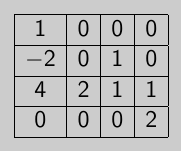

You can extract specific entries of an array `A` using the command `A(row, col).` For row and column vectors, you only need to supply a single index. We are going to try this with a matrix that is preloaded in the file `datafile.mat`.

% Load the file containing the matrix. 
% then print the matrix stored as 'data'
load datafile.mat
data

data = 7×4 single matrix
    0.9049    0.2622    0.4242    0.7303
    0.9797    0.6028    0.5079    0.4886
    0.4389    0.7112    0.0855    0.5785
    0.1111    0.2217    0.2625    0.2373
    0.2581    0.1174    0.8010    0.4588
    0.4087    0.2967    0.0292    0.9631
    0.5949    0.3188    0.9289    0.5468


Create a variable `x` that contains the value in the 6th row and 3rd column of the array `data`.

%% Code here.

x = data(6,3)

x = single
0.0292

You can also use the MATLAB keyword `end` to get and element in the last row or  column of an array. For example, the code

`y = A(end, 2)`

Returns the element in the last row and the 2nd column of a matrix `A. `

You try: Use the `end `keyword to obtain the value in the last row and 3rd column of the matrix `data.` Assign this value to a variable called `x.`

%% Code here.

x = data(end, 3)

x = single
0.9289

Note that you can combine arithmetic operations with the keyword `end. `Below, create a scalar variable `y `that contains the value in the second to last row and the last column of `data`.

%% Code here. 

y = data(end-1, end)

y = single
0.9631

Finally, you might be wondering what happens if we pass just a single index through a matrix. Run the following code. What does it output?

idx = 10

idx = 10

data(idx)

ans = single
0.7112

If you only use one index with a matrix, it will traverse down each column in order and stop at the specified number.

We can also extract an entire row or column using the `:` (colon) function. Run the following code. What does it return?

v = data(:,2)

v = 7×1 single column vector
    0.2622
    0.6028
    0.7112
    0.2217
    0.1174
    0.2967
    0.3188


You can use `:` as an index to extract all of the elements in a spefied row or column. You can extract multiple rows and columns as well. For example, the code

`x = A(1:3, :)`

creates a new array, called `x`, which contains the first, second and third rows of a matrix `A. `

You try: Create a new variable, called `minor` containing rows 4-6 and columns 1-2 of the matrix `data.`

%% Code here.

minor = data(4:6, 1:2)

minor = 3×2 single matrix
    0.1111    0.2217
    0.2581    0.1174
    0.4087    0.2967


Create a vector `p` containing the third through the last elements in the 2nd column of `data. `

%% Code here.

p = data(3:end, 2)

p = 5×1 single column vector
    0.7112
    0.2217
    0.1174
    0.2967
    0.3188


Finally, we will look at how to change values in an array. We will start by creating a vector `v2` containing the last column of `data. `

% Extract the last column of 'data'
v2 = data(:,end)

v2 = 7×1 single column vector
    0.7303
    0.4886
    0.5785
    0.2373
    0.4588
    0.9631
    0.5468


We can change elements of an array by combining indexing with assignment. For example:

`A(2,3) = 0.5`

changes the element in the 2nd row and 3rd column of `A` to 0.5. 

You try: Change last element of `data` to 0. 

%% Code here.

data(end) = 0

data = 7×4 single matrix
    0.9049    0.2622    0.4242    0.7303
    0.9797    0.6028    0.5079    0.4886
    0.4389    0.7112    0.0855    0.5785
    0.1111    0.2217    0.2625    0.2373
    0.2581    0.1174    0.8010    0.4588
    0.4087    0.2967    0.0292    0.9631
    0.5949    0.3188    0.9289         0


Finally, you can replace an entire row or column of vector using indexing. 

You try: Use indexing and the `zeros` function to replace the last row of `data` with a row of zeroes. 

%% Code here.

data(end,:) = 0

data = 7×4 single matrix
    0.9049    0.2622    0.4242    0.7303
    0.9797    0.6028    0.5079    0.4886
    0.4389    0.7112    0.0855    0.5785
    0.1111    0.2217    0.2625    0.2373
    0.2581    0.1174    0.8010    0.4588
    0.4087    0.2967    0.0292    0.9631
         0         0         0         0


Create a 4x4 identity matrix, by first create a matrix of all zeroes, and then replacing the appropriate entries. Store your matrix in a variable called `id4`.

%% Code here. 

id4 = zeros(4,4)

id4 =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


id4(1,1) = 1

id4 =      1     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


id4(2,2) = 1

id4 =      1     0     0     0
     0     1     0     0
     0     0     0     0
     0     0     0     0


id4(3,3) = 1

id4 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     0


id4(4,4) = 1

id4 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


Note: MATLAB has a built in identity matrix, `eye(n,n).`

## Operations on Arrays

We can perform the usual matrix operations (and more!) on arrays in MATLAB. 

You can add a scalar value to every entry of an array. For example:

`A+2`

adds 2 to every entry of an array `A`,

`2*A`

Multiplies every entry of an array `A `by the scalar 2, etc. 

You try: Create new vectors `v1` and `v2 `consisting of the 3rd and 4th rows of `M` respectively. 

%% Code here.

v1 = M(3,:)

v1 = 1×4 single row vector
    0.4889    0.8852    0.1366    0.9037


v2 = M(4,:)

v2 = 1×4 single row vector
    0.6241    0.9133    0.7212    0.8909


Add 1 to each element of `v1` and store the result in a variable named `r.`

%% Code here.

r = v1+1

r = 1×4 single row vector
    1.4889    1.8852    1.1366    1.9037


Create a vector `z` by adding `v1` and `v2.`

%% Code here.

z = v1+v2

z = 1×4 single row vector
    1.1130    1.7985    0.8578    1.7946


Divide every element of `z` by 2.

%% Code here.

z/2

ans = 1×4 single row vector
    0.5565    0.8992    0.4289    0.8973


There are also functions that can be applied to arrays in MATLAB. Run the following code and see what you get. 

z_max = max(z)

z_max = single
1.7985

z_round = round(z)

z_round = 1×4 single row vector
     1     2     1     2


The command `max` returns the maximum entry in an array. The command `round` will round every entry of an array to the nearest integer. Remember to check the MATLAB documentation to see what else you can do!

## Multiplication

Lastly, we will discuss multiplication of arrays. 

%% We create a 3x3 matrix A of random
%% integers between 1 and 20, and two
%% 3x1 vectors, x1, x2.

A = randi([1,20], 3, 3)

A =      8    15     1
    14     1     2
     4     6    17


x1 = [2:4]'

x1 =      2
     3
     4


x2 = linspace(10,20, 3)'

x2 =     10
    15
    20


Find the product of `A` and `x1.`

%% Code here.

A*x1

ans =     65
    39
    94


Even though we run far away from this in linear algebra courses, MATLAB allows us to perform element-wise multiplication as well, using `.* `(period followed by asterisk). 

Find the element-wise product of `x1` and `x2. `Store the result in a vector called `bad_mult`.

%% Code here. 

bad_mult = x1.*x2

bad_mult =     20
    45
    80


Error using  ^  (line 51)
Incorrect dimensions for raising a matrix to a power. Check that the matrix is square and the power is a scalar. To perform elementwise matrix powers, use '.^'.

That's it for this notebook! Up next, we will do more linear algebra with matrices.

## Disclaimers and References

*This notebook was written for the *[*The EDGE Program*](https://www.edgeforwomen.org/)* by Anila Yadavalli, Ph. D., 2021.*

*Redistribution of the material contained in this repository is conditional on acknowledgement of Anila Yadavalli, Ph.D.'s original authorship. *

*Many of the exercises in this notebook were inspired by the "MATLAB Onramp" course offered by the *[*MATLAB and Simulink Training Academy*](https://matlabacademy.mathworks.com/)*. *